# 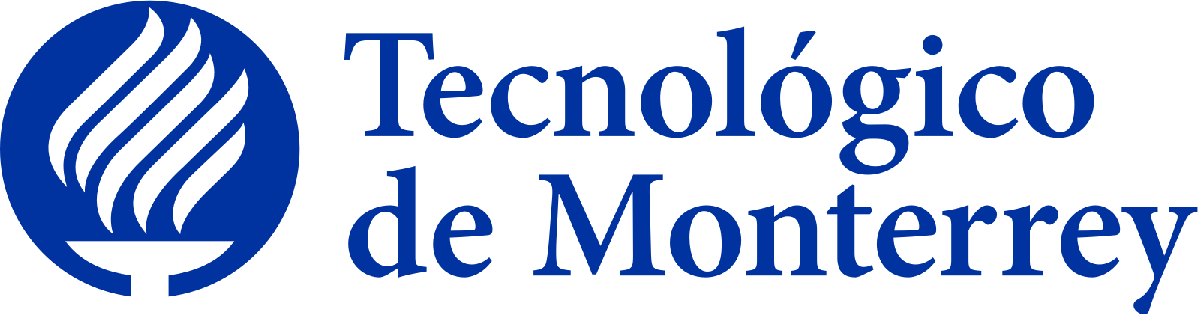

# Primer Avance del Reto

### Modelación computacional de sistemas eléctricos

Grupo: #210  Equipo: #

Entrega: Abril 9, 2024

Santiago Quintana Moreno A01571222, Diego Saldaña Gómez A01571609

Natalia Cavazos Almeida A01571724, Eduardo Vega A0119887

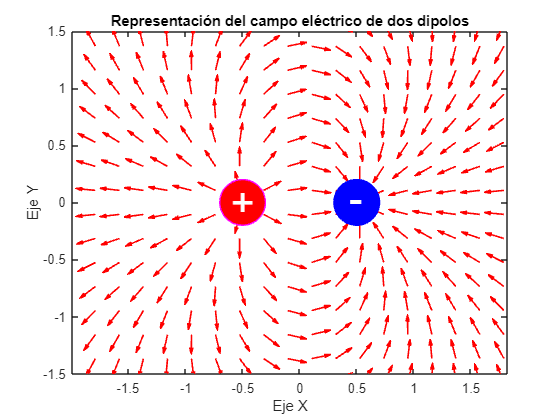

% Limpiar consola, terminal y variables
    clear;
    close all;
    clc;

% Constructor del Meshgrid
    N = 20;
    minX = -2; maxX = +2;
    minY = -2; maxY = +2;
    x = linspace(minX, maxX, N);
    y = linspace(minY, maxY, N);
    [xG, yG] = meshgrid(x, y);

% Posicion de la particula negativa
    xCn = 0.5; yCn = 0; a = 0.4;

% Posicion de la particula positiva
    xCp = -0.5; yCp = 0;

% Calculo del Campo electrico
    Qn = -20;
    Qp = +20;
    eps0 = 8.854e-12;
    kC = 1/(4*pi*eps0);
    Rx = xG - xCn;
    Ry = yG - yCn;
    R = sqrt(Rx.^2 + Ry.^2).^3;
    Ex = kC .* Qn .* Rx ./ R;
    Ey = kC .* Qn .* Ry ./ R;
    Rx = xG - xCp;
    Ry = yG - yCp;
    R = sqrt(Rx.^2 + Ry.^2).^3;
    Ex = Ex + kC .* Qp .* Rx ./ R;
    Ey = Ey + kC .* Qp .* Ry ./ R;
    E = sqrt(Ex.^2 + Ey.^2);

% Componentes x, y
    u = Ex./E;
    v = Ey./E;

% Constructor de la grafica
    figure();
    h = quiver(xG, yG, u, v, 'autoscalefactor', 0.6); % Declaración del quiver y ajuste de la grafía en los dipolos
    set(h, 'color', [1 0 0], 'linewidth', 1.2);
    axis([-1.5 1.5 -1.5 1.5]);
    axis equal;
    box on;
    h = rectangle('Position', [xCn-a/2, yCn-a/2, a, a], 'curvature', [1 1]);
    set(h, 'Facecolor', [0 0 1], 'Edgecolor', [0 0 1]);
    text(0.43, 0.05, '-', 'Color', 'white', 'FontSize', 30);
    h = rectangle('Position', [xCp-a/2, yCp-a/2, a, a], 'curvature', [1 1]);
    set(h, 'Facecolor', [1 0 0], 'Edgecolor', [1 0 1]);
    text(-0.6, 0, '+', 'Color', 'white', 'FontSize', 30);

% Añadimos etiquetas a los ejes y titulo a la grafica
    title("Representación del campo eléctrico de dos dipolos"); 
    xlabel('Eje X'); 
    ylabel('Eje Y'); 